### 问题三结果分析

载入数据

clear,clc
gig_pre = readtable("gig_pre.csv");

对predication列（模型得分）和binder列（真实结合情况）进行分析

pre_score = gig_pre.prediction;
binder = gig_pre.binder;


board = 0:0.01:1;
% 用临界值（应该是0.5）来划分
pre_score_higher = pre_score>=board;
% 用结合与否来划分
binder = logical(binder);

% P（查准率）、R（查全率）
disp("总数："+length(binder));%总数

总数：1783


disp("正例数："+sum(binder));%正例数

正例数：89


disp("反例数："+sum(~binder));%反例数

反例数：1694


error = sum(xor(pre_score_higher,binder));

TP = sum(pre_score_higher&binder);%真正例数量
TN = sum(~pre_score_higher&~binder);%真反例数量
FN = sum(~pre_score_higher&binder);%假反例数量
FP = sum(pre_score_higher&~binder);%假正例数量

R = TP./(TP+FP);
P = TP./(TP+FN);

TPR = TP./(TP+FN)

TPR =     1.0000    0.8539    0.8315    0.8202    0.8090    0.8090    0.8090    0.8090    0.7865    0.7865    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7753    0.7640    0.7640    0.7640    0.7640    0.7640    0.7640    0.7640    0.7640    0.7640    0.7640    0.7640


FPR = FP./(TN+FP)

FPR =     1.0000    0.1222    0.1051    0.0939    0.0868    0.0803    0.0785    0.0762    0.0726    0.0691    0.0679    0.0655    0.0649    0.0626    0.0614    0.0608    0.0590    0.0573    0.0561    0.0549    0.0549    0.0543    0.0531    0.0519    0.0508    0.0478    0.0472    0.0472    0.0466    0.0455    0.0443    0.0431    0.0425    0.0425    0.0419    0.0419    0.0413    0.0413    0.0413    0.0401    0.0390    0.0390    0.0390    0.0390    0.0384    0.0384    0.0378    0.0372    0.0360    0.0360


TPR = TPR(end:-1:1);
FPR = FPR(end:-1:1);


F1_score = (2*P.*R)./(P+R);


PR曲线

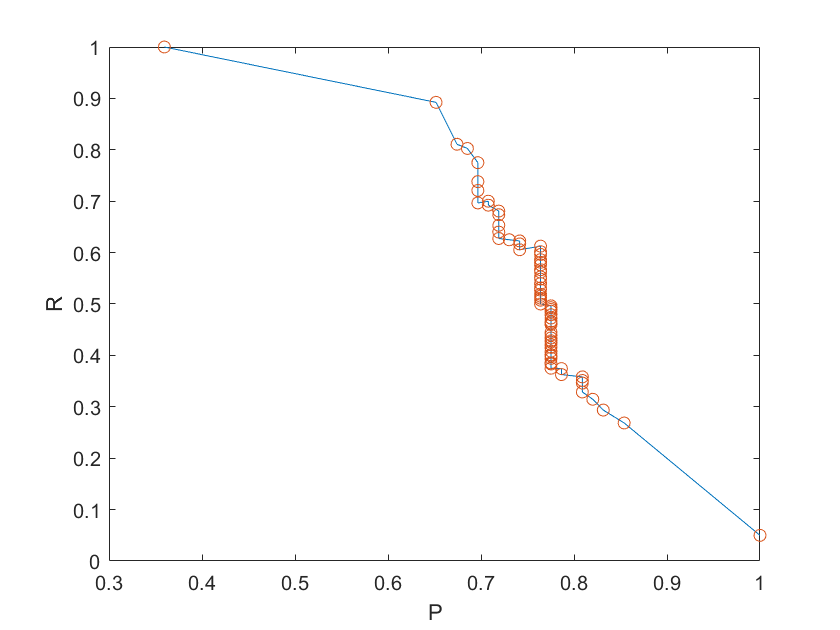

plot(P,R)
hold on
scatter(P,R)
xlabel('P')
ylabel('R')
hold off

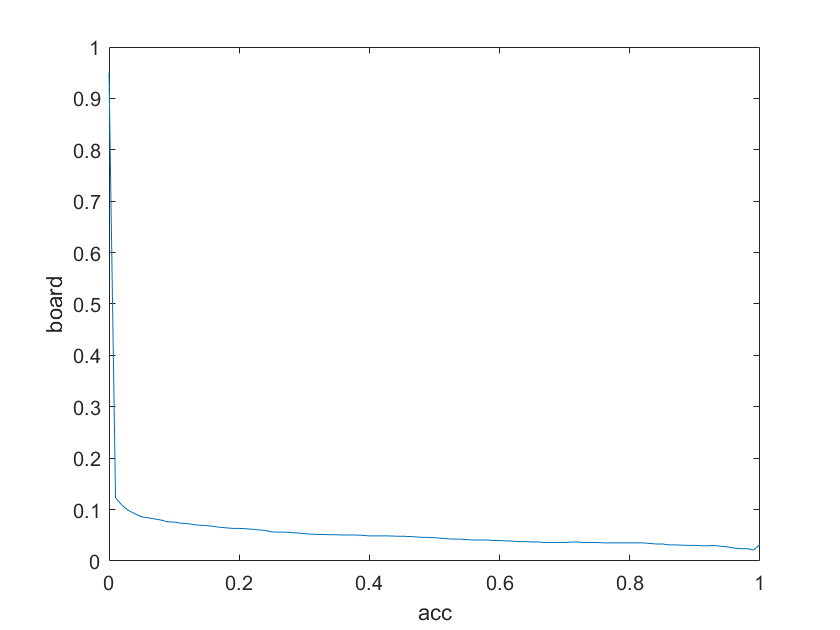


plot(board,error/length(binder));
xlabel('acc')
ylabel('board')

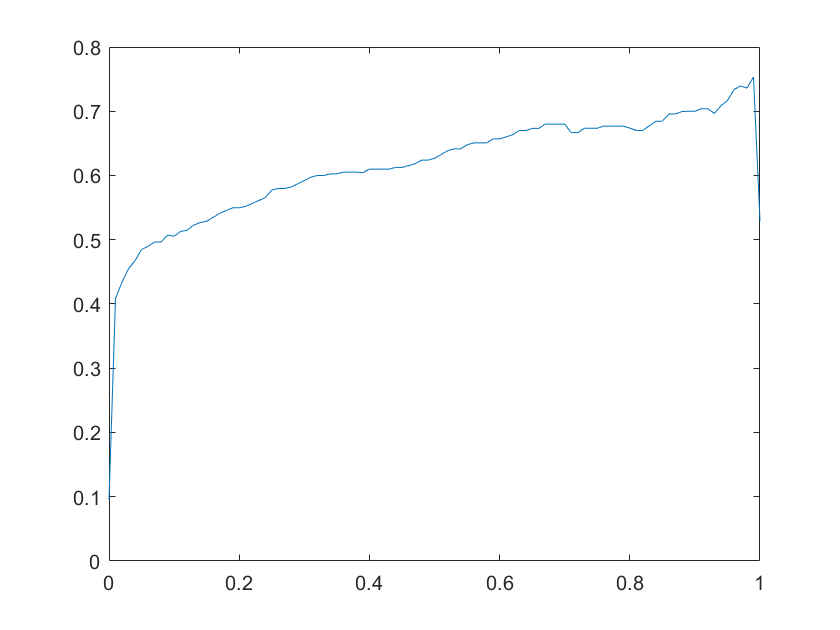

plot(board,F1_score);

AUC曲线

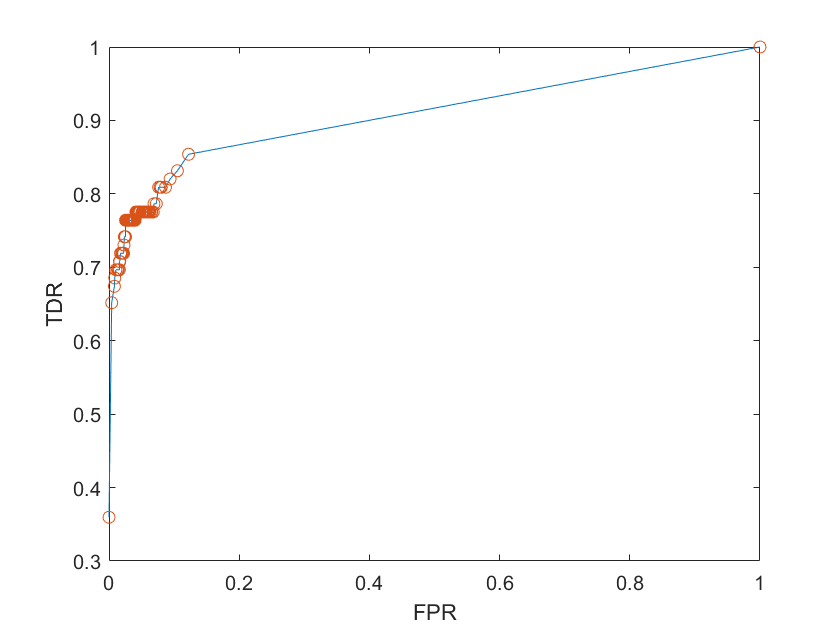

figure
plot(FPR(1:end),TPR(1:end));
hold on
scatter(FPR,TPR)
xlabel('FPR')
ylabel('TDR')
hold off

AUC = 1/2*sum(diff(FPR).*(TPR(1:end-1)+TPR(2:end)))

AUC = 0.9080